# Contour Extraction I

In this problem, you will use morphological erosion to extract the contours or the circular boundaries of coins in a given image.

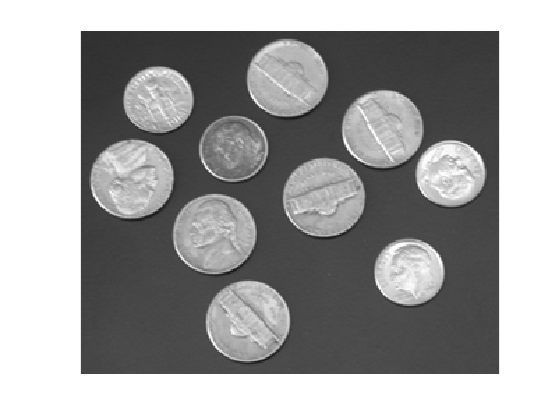

I = imread("coins.png");                        % Read a binary image
figure;
imshow(I)        

As a first step, you must convert the grayscale coins image into a binary image, such that the brighter objects in the foreground (coins in this case) become completely bright (`1`) and the darker background becomes completely dark (`0`). To do this, you will threshold the gray intensities of the image.

a. Adjust the scalar threshold level between `0` and `255`. Try and ensure that all parts of the image containing coins are converted to white (`logical 1`) as best as possible.

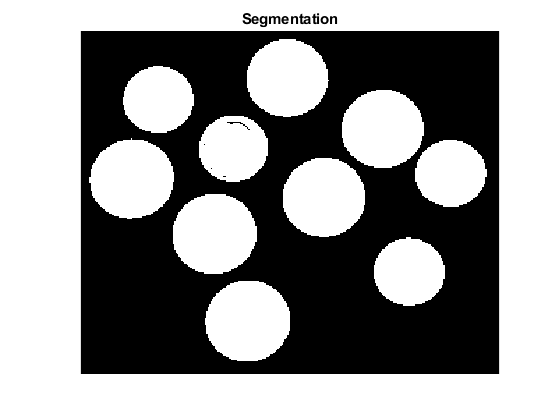

BWCoins = I > 95;        % Relational operation returns a logical output (binary image)
imshow(BWCoins);
title("Segmentation")

This is your segmentation result. A good segmentation will set you up to get more accurate coin boundaries at the end.

b. Create a disk-shaped structuring element with a radius of `1`. Use the `strel` function.

SE = strel("disk",1);

c. Erode the segmentation output `BWcoins` using the structuring element `SE`. Use the `imerode` function.

BWCoinsEroded = imerode(BWCoins,SE);

d. Get the coins' boundaries by combining the binary images (`BWCoins` and `BWCoinEroded`) using the appropriate logical operators. This should give you a thin boundary surrounding the coins.

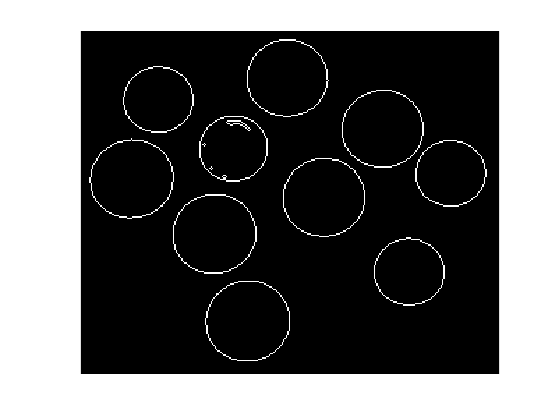

BWCoinsContour = BWCoins & ~BWCoinsEroded;
imshow(BWCoinsContour)

Notice how one of the coins has contours inside it because of incomplete segmentation in step a.

# Contour Extraction II

In Contour Extraction I, you applied basic morphology and logical operations to get the boundaries of coins. The first step to do this was to binarize the image to get the coins as foreground (white) and everything else as background (black).

a. Read the image and apply a threshold to the gray intensities to get a binary mask of coins.

I = imread("coins.png");                          % Read a binary image
figure;
imshow(I)

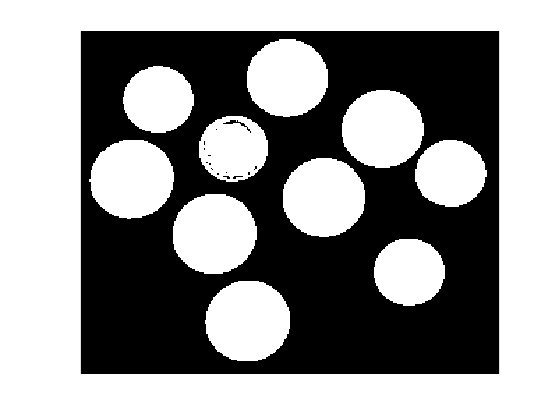

BWCoins = I > 100;         % Relational operation returns a logical output (binary image)
imshow(BWCoins)                                     

b. To "close" any small holes in the coins (foreground), apply the closing operation to `BWCoins` with a disk of radius `1` `o`r `2`. 

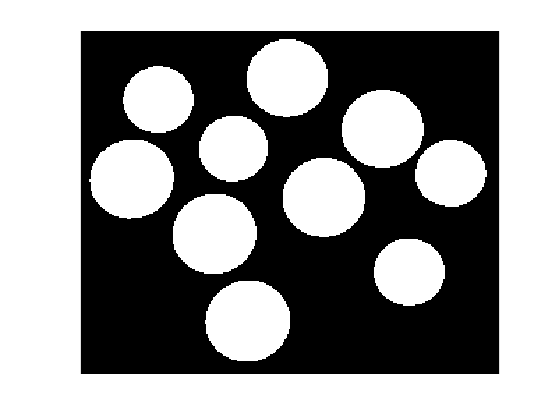

SE = strel("disk",2);                        % Create a structuring element
BWCoinsClosed = imclose(BWCoins,SE);             % Closing
imshow(BWCoinsClosed)

c. To remove any tiny specks of white in the black background, apply the opening operation to `BWCoinsClosed` with a disk of radius `1` `o`r `2`. 

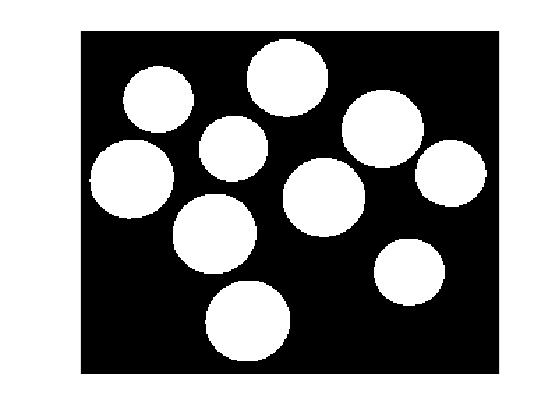

SE = strel("disk",1);                        % Create a structuring element
BWCoinsOpened = imopen(BWCoinsClosed,SE);             % Opening
imshow(BWCoinsOpened)

d. Extract the contours by first eroding `BWCoinsClosed` with a tiny disk element and then excluding the eroded result from `BWCoinsClosed`.

SE = strel("disk",1)                              % Create a structuring element

SE = strel is a disk shaped structuring element with properties:

      Neighborhood: [3×3 logical]
    Dimensionality: 2


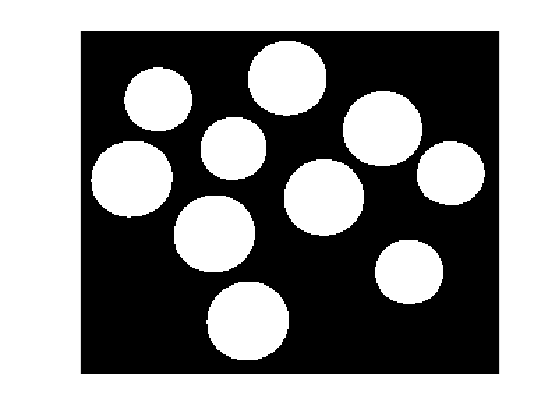

BWCoinsEroded = imerode(BWCoinsOpened,SE);        % Erosion
imshow(BWCoinsEroded)

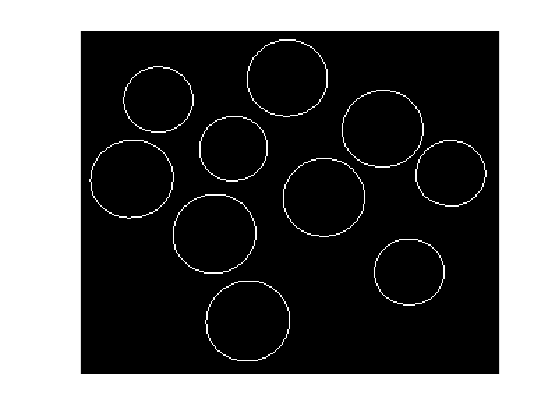

               
BWContour = BWCoinsOpened & ~BWCoinsEroded;       % Retain the boundaries of the coins by excluding the eroded coins from the closed coins
imshow(BWContour)

Depending on your chosen threshold for the segmentation, you will have to adjust the size of the structuring elements for opening and closing operations.

# Identifying Nickels

In this exercise, you will use morphological and logical operations to separate the nickels from the dimes in `coins.png`. 

Import the image and segment it using a relational operator to get the binary mask of coins.

I = imread("coins.png");
imshow(I)

a. Measure the sizes (radii) of the two types of coins in the image. 

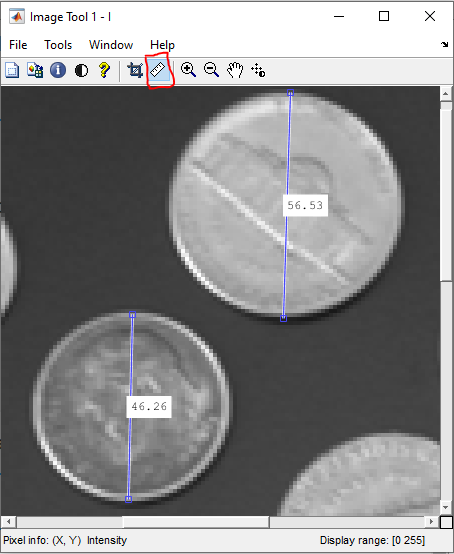

Select an integer-valued radius for a disk-shaped structuring element in between these two. 

radiusSE = 25

radiusSE = 25

b. Apply morphological opening to `BWCoins` with the disk-shaped structuring element of radius `radiusSE` determined in step a.

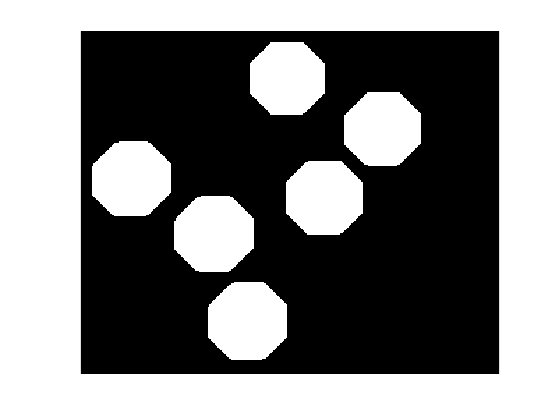

BWCoins = I > 100;

SE = strel("disk",radiusSE);    
BWCoinsOpened = imopen(BWCoins,SE);
imshow(BWCoinsOpened)

c. Dilate `BWCoinsOpened` with a small disk-shaped structuring element. Pick a radius such that the foreground objects (white pixels) in the dilated image will completely encompass the regions containing nickels without the shapes overlapping.

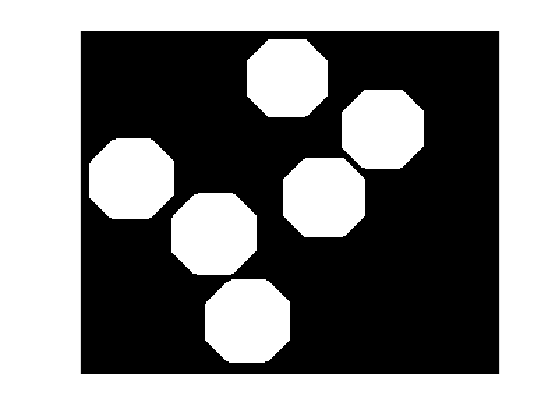

SE = strel("disk",3);
BWCoinsDilated = imdilate(BWCoinsOpened,SE);
imshow(BWCoinsDilated)

d. Use a logical operator to combine `BWCoinsDilated` (result from step d) with `BWCoins` (the segmented coins) to retain the nickels (large circles) and eliminate the dimes (small circles).

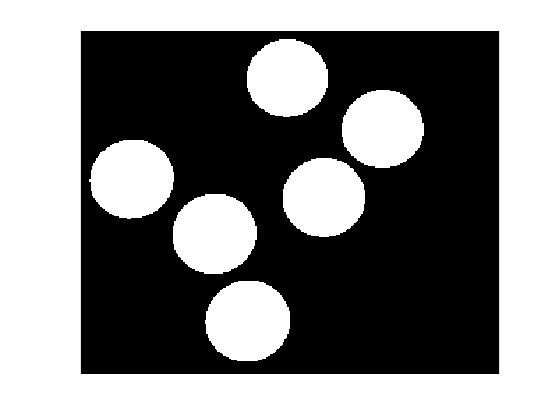

BWNickels = BWCoins & BWCoinsDilated;
imshow(BWNickels)

e. Extract the coins from the original image. The elements in the original grayscale image corresponding to the `1`s in `BWNickels` will be retained, while all other parts of the original image will be set to `0.`

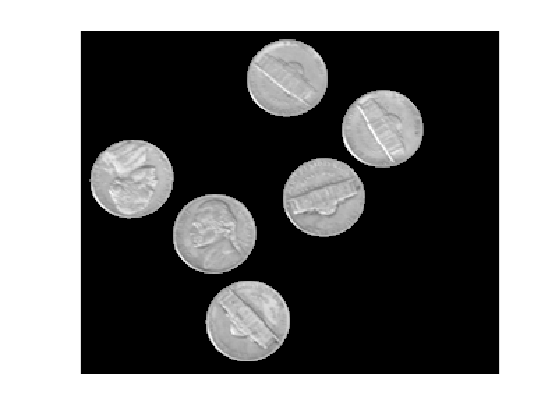

nickels = I .* uint8(BWNickels);
imshow(nickels)